## Computer Exercises 1 - EPFL 2024

#### Hugo Penichou

#### Matthieu Scharffe

clc
clear all
close all

### 1.1 Norms of SISO system

The SISO system under study has the following transfer function :

## 
$$G(s)=\frac{s-1}{s^2+2s+10}$$


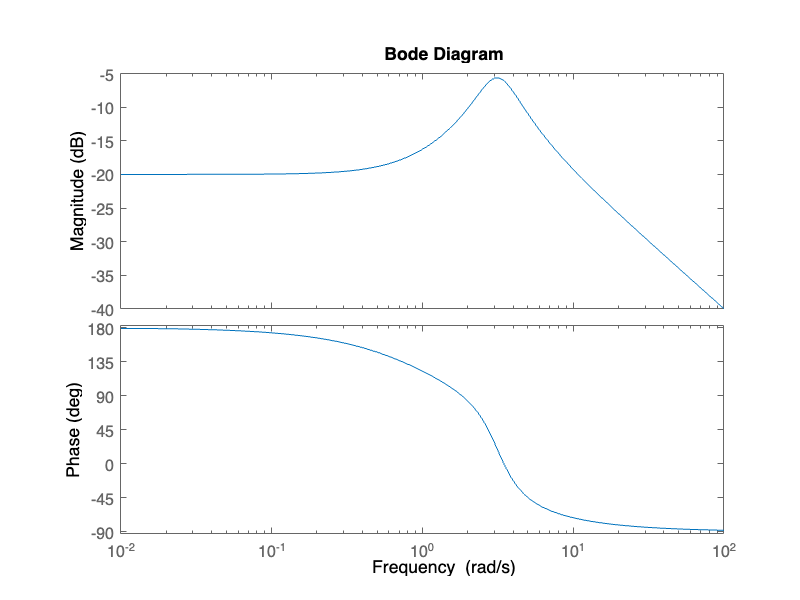

num_siso=[1,-1];
den_siso=[1,2,10];
G_siso=tf(num_siso,den_siso);
bode(G_siso);

The state-space model takes the following form :

[A_siso,B_siso,C_siso,D_siso]=tf2ss(num_siso,den_siso);

## 
$$A= \left[\matrix{ -2 & -10 \cr 1 &0} \right] \ \ \ \ \ \  B= \left[\matrix{ 1  \cr 0} \right]

$$


## 
$$C= \left[\matrix{1 & -1} \right] \ \ \ \ \ \  D= 0$$


### 1.1.1 2-Norm

#### Frequency response

g = @(omega) abs(squeeze(freqresp(G_siso,omega))).^2 ;

omega_min_max = 10000 ;
omega_stamp = 0.7 ; 
omega_values = -omega_min_max:omega_stamp:omega_min_max ;

FreqNormSISO = sqrt( sum(g(omega_values) * omega_stamp ) / (2*pi) ) ; 

disp( FreqNormSISO ) 

    0.5244



#### Impulse response

T = linspace(0,5,5000) ; 
[ Y , T ] = impulse(G_siso, T) ; 

ImpulseNormSISO = (trapz(T,abs(Y).^2))^0.5 ; 

disp(ImpulseNormSISO) ; 

    0.5244



#### State-space method

[A,B,C,D] = ssdata(G_siso) ; 

LSISO = are(A', zeros(2,2), B*B') ; 
SSNormSISO = sqrt( trace(C*LSISO*C') ) ; 

disp(SSNormSISO) ; 

    0.5244



#### True norm

TrueNormSISO = norm(G_siso, 2) ;
disp( TrueNormSISO ) ; 

    0.5244



### 1.1.2 $\infty$-NORM

The Bode diagram shows that the maximum value of $|G(j\omega)|$ is to be found for $\omega \in [1Hz ; 10Hz]$.

#### Frequency response

We propose two derivations of the frequency response method. The first one is analytic and gives the exact results, the other one is purely numerical.

Let's start by computing the square of the modulus of $G(j\omega)$ :

### 
$$\begin{array}{rcl}
\vert G(jw) \vert^2 &=& \frac{1+\omega^2}{(10-\omega)^2+4\omega^2} \\
&=& \frac{1+\omega^2}{100-16\omega^2 + \omega^4}
\end{array}$$


The derivative is given by :

### 
$$\frac{d \vert G(j\omega) \vert^2}{d\omega}= -2\omega \frac{\omega^4 + 2\omega^2 -116}{({100-16\omega^2 + \omega^4)^2}$$


We are looking for the extremas of the function :

### 
$$\frac{d \vert G(j\omega) \vert^2}{d\omega}= 0 \Leftrightarrow \omega^4 + 2\omega^2 -116=0$$


This 4-th order polynomia can easily be solved with a change of variable $X=\omega^2$. The root expression is :

### 
$$\omega_{max}^2=\sqrt{117}-1$$


which leads to the value of the infinite norm :

### 
$$\Vert G \Vert_{\infty} = \sqrt{\frac{\sqrt{117}}{234 - 18\sqrt{117}}} \approx 0.5246$$


Now let's do this computation with a numerical method.

%% Frequency response-numerical method
N_points_siso=100;
%The max is between 1 Hz and 10 Hz
omega_siso=logspace(0,1,N_points_siso);

norm_freq_resp_array_siso=freqresp(G_siso,omega_siso);

norm_frq_resp_siso=max(abs(norm_freq_resp_array_siso))

norm_frq_resp_siso = 0.5246

#### Bisection Algorithm

The bisection algorithm relies on a function named "upper_or_lower" that can be found in the appendix. It is the transcription in matlab of the bounded real lemma.

%% Bisection algorithm

gamma_l=0;
gamma_u=1;
epsilon=0.0001;

while (gamma_u-gamma_l)/gamma_l >= epsilon
    gamma=(gamma_u+gamma_l)/2;
    bool=upper_or_lower(gamma,A_siso,B_siso,C_siso);
    if bool==1
        gamma_l=gamma;
    else
        gamma_u=gamma;
    end
end

n_bisection_siso=(gamma_u+gamma_l)/2

n_bisection_siso = 0.5246

#### Matlab infinite norm

n_matlab_siso=norm(G_siso,inf)

n_matlab_siso = 0.5246

The three methods give the same value for infinite norm of $G
$ that is : $\Vert G \Vert_{\infty} \approx 0.5246$.

### 1.2 Norms of MIMO system

The MIMO system under study has the following state-space representation :

### 
$$A= \left[\matrix{ 20 & -27&7 \cr 53 &-63&13 \cr -5&12&-8} \right] \ \ \ \ \ \  B= \left[\matrix{ 1 &-1 \cr -2&-1 \cr -3&0} \right]
$$


### 
$$C= \left[\matrix{ 0 & 0&-2 \cr 1 &-1&-1} \right] \ \ \ \ \ \  D= \left[\matrix{ 0&0  \cr 0&0} \right]
$$


%% State-space system

A_mimo=[20,-27,7;
    53,-63,13;
    -5,12,-8];

B_mimo=[1,-1;
    -2,-1;
    -3,0];

C_mimo=[0,0,-2;
    1,-1,-1];

D_mimo=[0,0;
    0,0];

sys_mimo=ss(A_mimo,B_mimo,C_mimo,D_mimo);

G_mimo=tf(sys_mimo)

G_mimo =
 
  From input 1 to output...
           6 s^2 + 316 s - 36
   1:  --------------------------
       s^3 + 51 s^2 + 394 s + 486
 
           6 s^2 + 224 s + 48
   2:  --------------------------
       s^3 + 51 s^2 + 394 s + 486
 
  From input 2 to output...
               14 s + 432
   1:  --------------------------
       s^3 + 51 s^2 + 394 s + 486
 
               4 s + 234
   2:  --------------------------
       s^3 + 51 s^2 + 394 s + 486
 
Continuous-time transfer function.


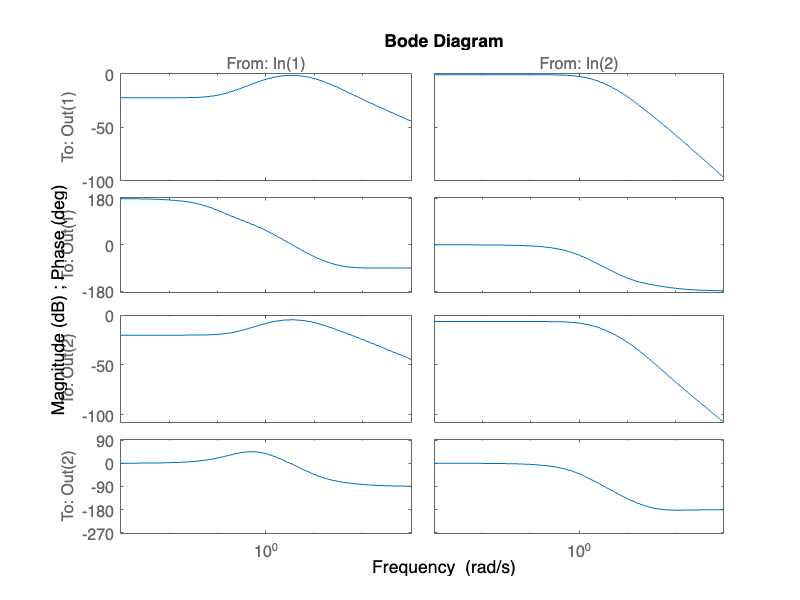


bode(G_mimo);

The transfer function takes the following form:

## 
$$G(s)= \frac{1}{s^3 +51s^2 +394s +486} \left[\matrix{ 6s^2 + 316s - 36 & 14s + 432 \cr 6s^2 + 224s +48 & 4s +234} \right]$$


### 1.2.1 2-Norm

#### Frequency response

G = @(omega) freqresp( sys_mimo , omega ) ;

G_conj = @(omega) ctranspose(freqresp( sys_mimo , omega )) ;
tr = @( omega ) trace(G_conj( omega )*G( omega )) ;

omega_min_max = 1000 ;
omega_stamp = 0.1    ; 
omega_values = -omega_min_max:omega_stamp:omega_min_max ;

integrand_values = zeros(size(omega_values));

for i = 1:length(omega_values)
    integrand_values(i) = tr(omega_values(i)) ;
end

FreqNormMIMO = sqrt( sum( integrand_values * omega_stamp ) / (2*pi) ) ;

disp( FreqNormMIMO ) ; 

    2.2767



#### State-space method

LMIMO = are(A_mimo', zeros(3,3), B_mimo*B_mimo') ; 
SSNormMIMO = sqrt( trace(C_mimo*LMIMO*C_mimo') ) ;

disp( SSNormMIMO ) ; 

    2.2818



#### True norm

TrueNormMIMO = norm( sys_mimo , 2 ) ; 
disp( TrueNormMIMO ) ; 

    2.2818



### 1.2.2 $\infty$-NORM

The Bode diagram shows that the maximum value of $|G(j\omega)|$ is to be found for $\omega \in [0.1Hz ; 10Hz]$.

#### Frequency response

%% Frequency response
N_points_mimo=100;

%The max is between 1 Hz and 10 Hz
omega_mimo=logspace(-1,1,N_points_mimo);

n_freq_resp_array_mimo=freqresp( G_mimo , omega_mimo ) ;

norm_2_freq_mimo=zeros( 1, N_points_mimo );

for i=1:N_points_mimo
    norm_2_freq_mimo(i)=norm( n_freq_resp_array_mimo(:,:,i));
end

n_freq_resp_mimo=max(norm_2_freq_mimo)

n_freq_resp_mimo = 1.1081

#### Bisection algorithm

%% Bisection algorithm

gamma_l=1;
gamma_u=1.3;
epsilon=0.0001;

while (gamma_u-gamma_l)/gamma_l >= epsilon
    gamma=(gamma_u+gamma_l)/2;
    bool=upper_or_lower( gamma , A_mimo , B_mimo , C_mimo );
    if bool==1
        gamma_l=gamma;
    else
        gamma_u=gamma;
    end
end

n_bisection_mimo=(gamma_u+gamma_l)/2

n_bisection_mimo = 1.1081

#### Matlab infinite norm

n_matlab_mimo=norm(G_mimo,inf)

n_matlab_mimo = 1.1081

The three methods give the same value for infinite norm of $G
$ that is : $\Vert G \Vert_{\infty} \approx 1.1081$.

## 1.3 Uncertainty modeling

### Appendix

function bool=upper_or_lower(gamma,A,B,C)
    H=[A,gamma^(-2)*B*B';
        -C'*C,-A'];
    eigenvalues=eig(H);
    
    if any(abs(real(eigenvalues)./abs(eigenvalues))<10^(-4)) 
        % The above condition means that there is one imaginary eigenvalue
        %  if it equals 1. The real part might be nonzero but very close
        %  to zero like for instance : 10^-15. It is a way to round it. 
        bool=1;
    else
        bool=0;
    end
end